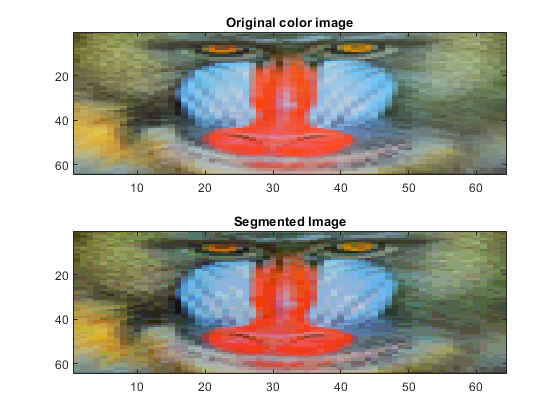

image_file_color ='BaboonRGB.bmp';
mean_shift_segmentation_color(image_file_color)

function mean_shift_segmentation_color(image_file_color)
   h=20; %set the bandwidth to be 20
   color1 = double(imread(image_file_color));  
   get_pixel_numbers = size(color1,1); 
   resize_fraction = 64/get_pixel_numbers;
   color1 = imresize(color1, resize_fraction);%resize the 512*512 image to 64*64
   figure; %create the figure window
   subplot(2,1,1);
   imagesc(uint8(color1));
   title("Original color image");
   
   new_image = zeros(64,64,3); %new_image is going to be the filtered image by mean shift, here I initialed a new matrix
   segmentation_image = zeros(64,64,3);
   for i = 1:64
    for j = 1:64
    iteration = 10;
    mean_color = [i,j,color1(i,j,1),color1(i,j,2),color1(i,j,3)]; %set the mean at an arbitrary location first
     while(iteration>0) 
        numerator = 0;
        denominator = 0;       
        
        for i1 = 1:64
           for j1 = 1:64
              % Weight calculation in Gaussian kernel
              weight = exp(-1 * ((mean_color(1) - i1)^2 + (mean_color(2) - j1)^2 + (mean_color(3) - color1(i1,j1,1))^2 + (mean_color(4) - color1(i1,j1,2))^2 + (mean_color(5) - color1(i1,j1,3))^2)/h);
              numerator = numerator + weight * [i1,j1,color1(i1,j1,1),color1(i1,j1,2),color1(i1,j1,3)];
              denominator = denominator + weight;
              
           end
           
        end
       new_mean_color = numerator / denominator; %calculate the new mean
        mean_shift =new_mean_color - mean_color; % calculate the mean shift vector
        get_meanshift_norm=(norm(mean_shift/h))^2; 
        if(get_meanshift_norm<0.1) %set up stopping criteria and let convergence threshold be 0.1
           iteration = 0; 
        end
        mean_color =new_mean_color;         
        iteration = iteration - 1;
     end
    new_image(i,j,1:3) = mean_color(3:5);
     
    segmentation_image(i,j,1:3) = (floor(new_image(i,j,1:3)/20))* 20;
          %There are pixels with minor differences, I take a bin size of 20 and get the floor value after the division, which will group these pixels in the same cluster
    end
  end 
  subplot(2,1,2);
  imagesc(uint8(segmentation_image));
  title("Segmented Image");
end

